# KF tuning with fminsearch optimization

The search variables $x_1 ,x_2$ are the exponents of $q_i =e^{x_1 }$ and $q_F =e^{x_2 }$ to ensure positiveness

clc
clf
clear all
close all
rng(0)

## Load data

data = load('KF_TuningData.mat').out';

## Initialize

qi_init = 1e-5;
qF_init = 1e-5;
x_init = log([qi_init, qF_init]);

## Cost function wrapper

do_plot = false;
obj_fcn = @(u) KF_simulate(struct('qi', exp(u(1)), 'qF', exp(u(2))), data, do_plot);

## Optimize

options = optimset('Display', 'iter', ...
                   'TolFun', 1e-10, ...
                   'TolX', 1e-10, ...
                   'MaxIter', 1000);

tic
[x_opt, cost_min] = fminsearch(obj_fcn, x_init, options);

 
 Iteration   Func-count         f(x)         Procedure
     0            1      0.000106311         
     1            3      0.000106311         initial simplex
     2            5      7.64464e-05         expand
     3            7      5.52053e-05         expand
     4            9      3.65838e-05         reflect
     5           11      3.61083e-05         contract outside
     6           13      3.61083e-05         contract inside
     7           15      3.61083e-05         contract inside
     8           17      3.61083e-05         contract inside
     9           19      3.46649e-05         expand
    10           21      3.17749e-05         expand
    11           23      1.43092e-05         expand
    12           25      2.43814e-06         expand
    13           27      1.96174e-07         reflect
    14           29      1.47204e-07         reflect
    15           31      1.47204e-07         contract outside
    16           33      1.13191e-07         contract insi

toc

Elapsed time is 117.841867 seconds.



qi_opt = exp(x_opt(1));
qF_opt = exp(x_opt(2));
fprintf('%.10f', qi_opt)

26782966.5298167467

fprintf('%.10f', qF_opt)

26426.5604653046

Optimal qF/qi ratio

0.0009866928

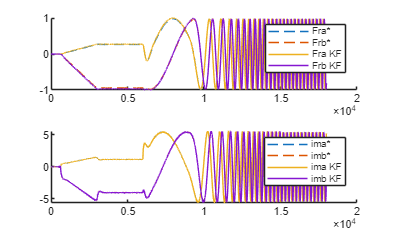

ans = 8.9060e-08

fprintf('%.10f', qF_opt / qi_opt)